clear
trainingFile = "tower_crane_sine_test_data.mat";
validationFile = "tower_crane_square_test_data.mat";
output = "arm"

output = "arm"

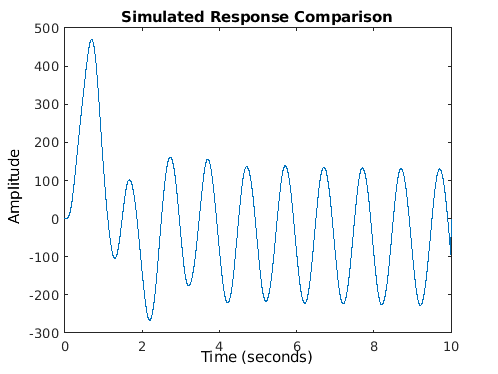

Ts = 0.002;

trainingStruct = load(trainingFile);
validationStruct = load(validationFile);
[t, y, u] = extractData(trainingStruct, output);
[t_val, y_val, u_val] = extractData(validationStruct, output);
dy = myDiff(y, Ts);
dy_val = myDiff(y, Ts);
plot(t, dy)

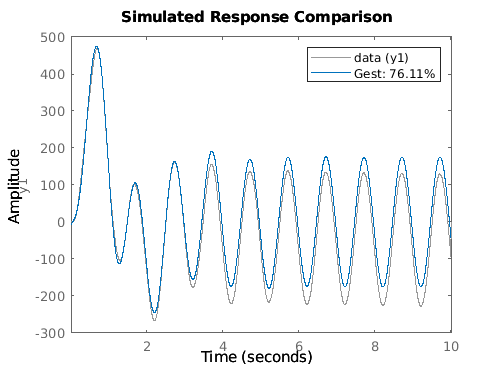


data = iddata(dy, u, Ts);
data_val = iddata(dy_val, u_val, Ts);

Gest = tfest(data, 2);
compare(data, Gest);

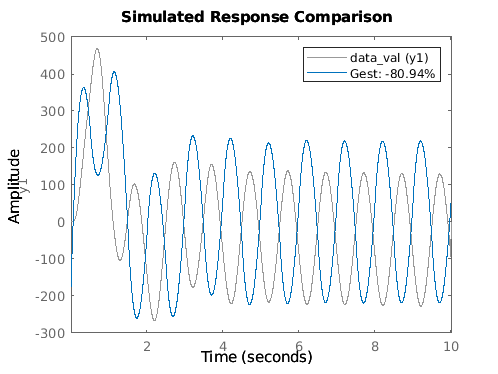

compare(data_val, Gest);

% centered difference of order 1

function dy = myDiff(y, h)
    n = length(y);
    dy = zeros(n,1); % preallocate derivative vectors
    for i=2:n-1
        dy(i) = (y(i-1)+y(i+1))/2/h;
    end
    
end